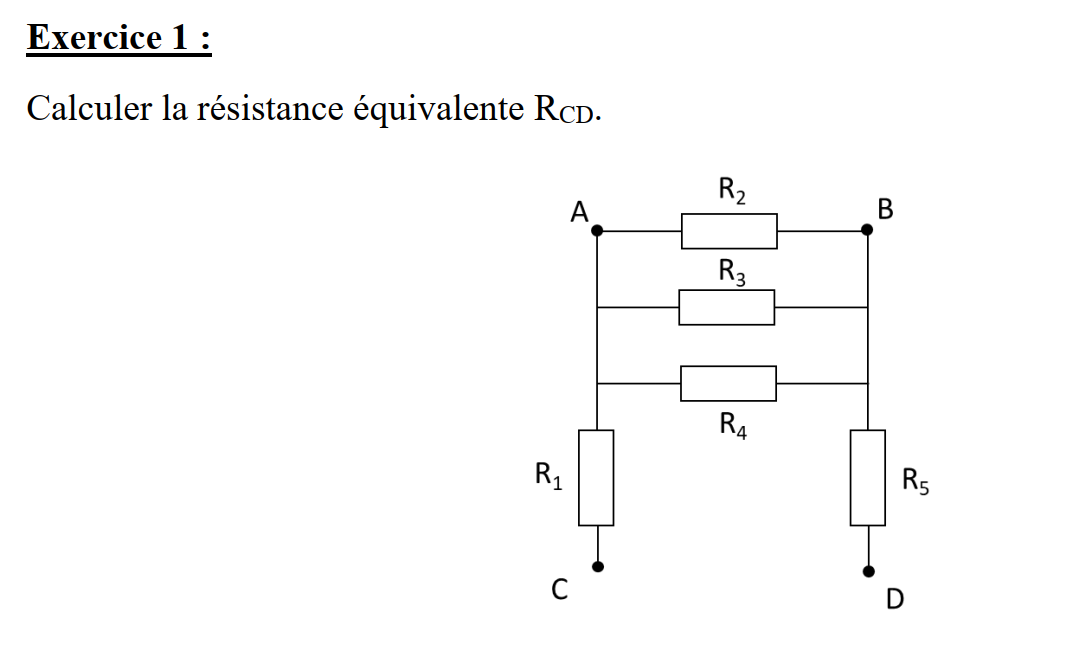

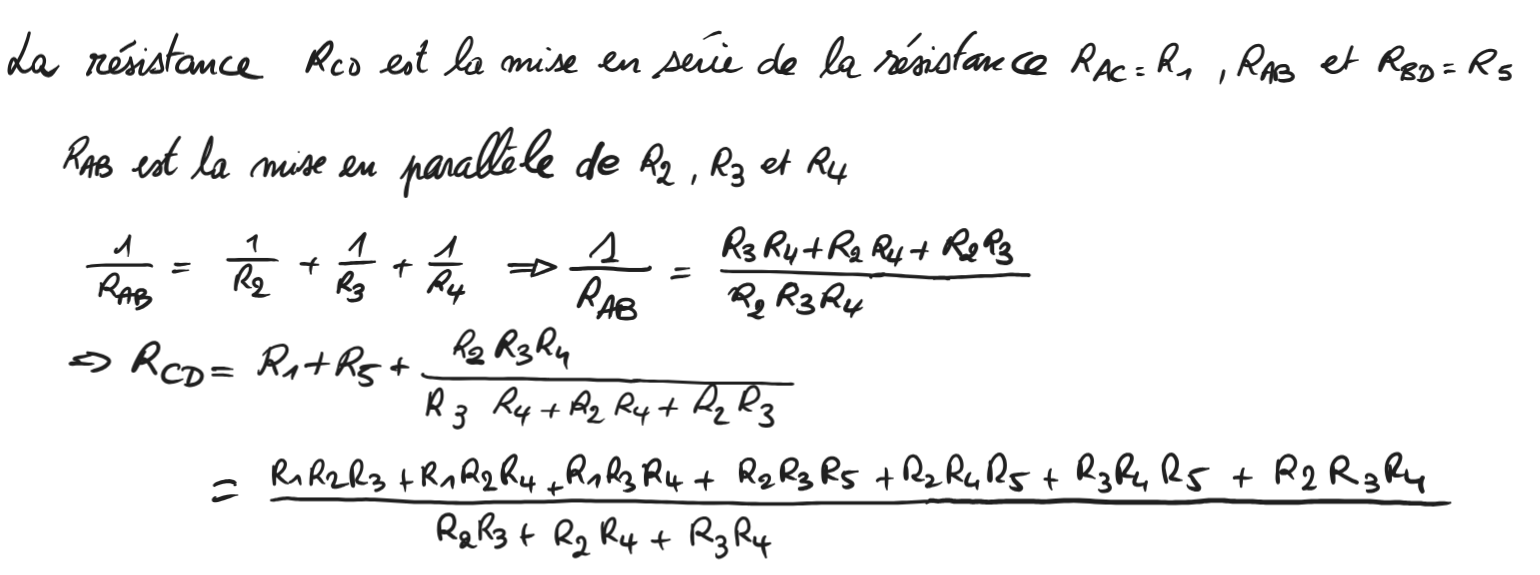

syms R1 R2 R3 R4 R5
RAB=1/(1/R2+1/R3+1/R4)

$$RAB = \frac{1}{\frac{1}{R_{2}}+\frac{1}{R_{3}}+\frac{1}{R_{4}}}$$

RCD=R1+R5+RAB

$$RCD = R_{1}+R_{5}+\frac{1}{\frac{1}{R_{2}}+\frac{1}{R_{3}}+\frac{1}{R_{4}}}$$

simplify(RCD)

$$ans = R_{1}+R_{5}+\frac{1}{\frac{1}{R_{2}}+\frac{1}{R_{3}}+\frac{1}{R_{4}}}$$

Cette forme est la plus simple pour matlab (le critère de "simplicité" est  le nombre de caractères minimum de l'expression)

On peut forcer matlab à ecrire $R_{CD}$ sous forme d'une fraction rationnelle :

simplifyFraction(RCD)

$$ans = \frac{R_{1}\,R_{2}\,R_{3}+R_{1}\,R_{2}\,R_{4}+R_{1}\,R_{3}\,R_{4}+R_{2}\,R_{3}\,R_{4}+R_{2}\,R_{3}\,R_{5}+R_{2}\,R_{4}\,R_{5}+R_{3}\,R_{4}\,R_{5}}{R_{2}\,R_{3}+R_{2}\,R_{4}+R_{3}\,R_{4}}$$

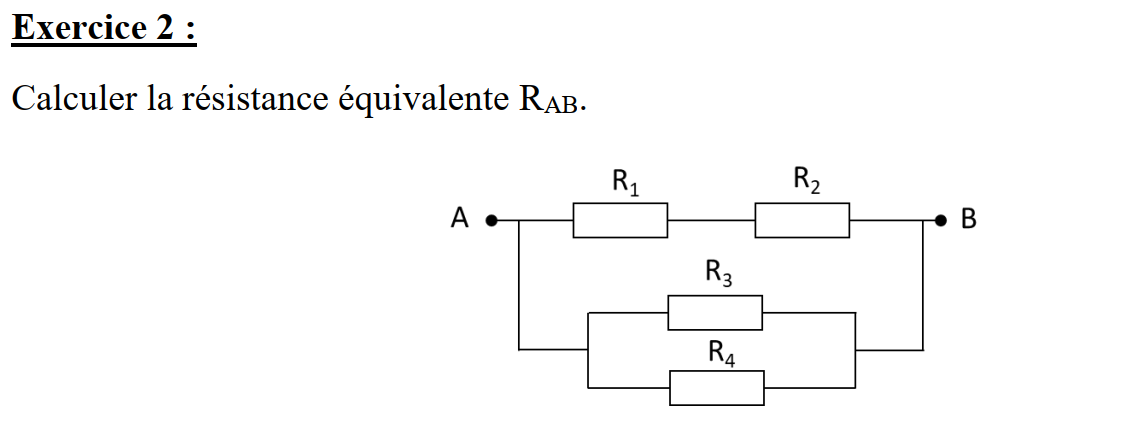

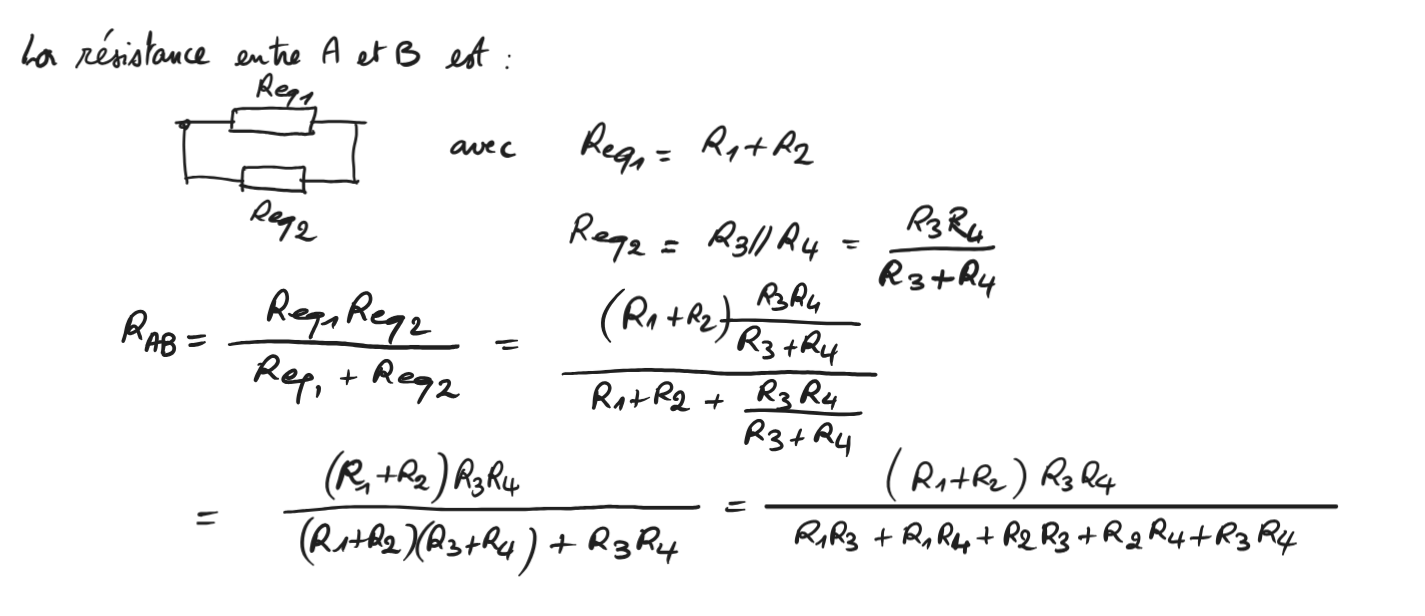

syms R1 R2 R3 R4
Req1=R1+R2

$$Req1 = R_{1}+R_{2}$$

Req2=R3*R4/(R3+R4)

$$Req2 = \frac{R_{3}\,R_{4}}{R_{3}+R_{4}}$$

RAB=Req1*Req2/(Req1+Req2)

$$RAB = \frac{R_{3}\,R_{4}\,\left(R_{1}+R_{2}\right)}{\left(R_{3}+R_{4}\right)\,\left(R_{1}+R_{2}+\frac{R_{3}\,R_{4}}{R_{3}+R_{4}}\right)}$$

simplifyFraction(RAB)

$$ans = \frac{R_{3}\,R_{4}\,\left(R_{1}+R_{2}\right)}{R_{1}\,R_{3}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{2}\,R_{4}+R_{3}\,R_{4}}$$

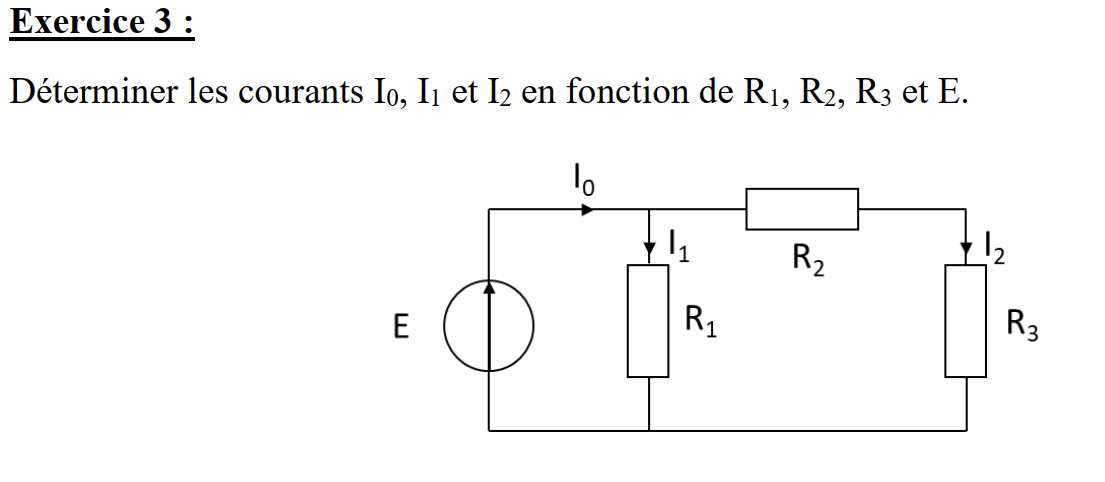

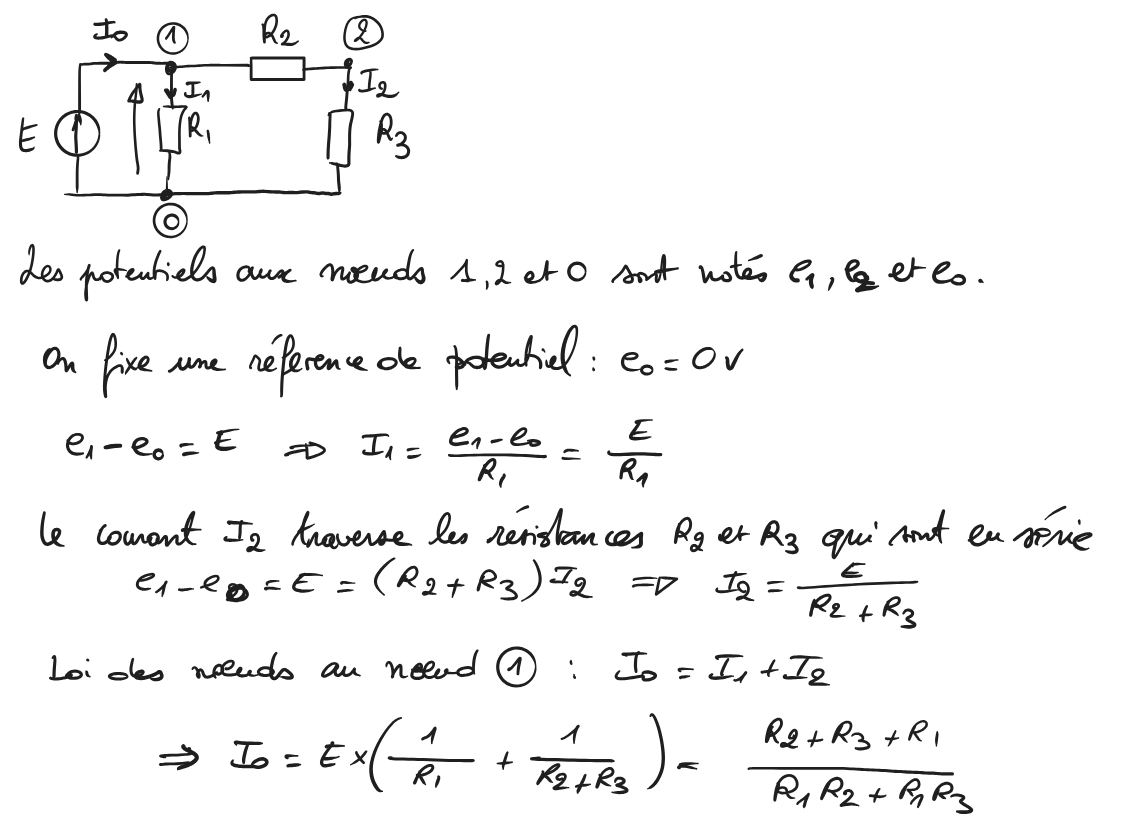

Utilisation de fspice :

Definition du circuit par la variable netlist :

netlist={
    'V1 1 0 E'
    'R1 1 0 R1'
    'R2 1 2 R2'
    'R3 2 0 R3'
    };
[X,name]=fspice(netlist)

** fspice 2.46  ** (c) Frederic Martinez


$$X = \left(\begin{array}{c} \text{E}\\ \frac{\text{E}\,R_{3}}{R_{2}+R_{3}}\\ -\frac{\text{E}\,\left(R_{1}+R_{2}+R_{3}\right)}{R_{1}\,\left(R_{2}+R_{3}\right)} \end{array}\right)$$

name = 1×3 cell array
    {'V(1)'}    {'V(2)'}    {'I(V1)'}


Par convention, le courant débité par la source de tension $I(V1)=-I_0$

On obtient donc :

I0=-X(3)

$$I0 = \frac{\text{E}\,\left(R_{1}+R_{2}+R_{3}\right)}{R_{1}\,\left(R_{2}+R_{3}\right)}$$

Pour obtenir les courants $I_1$ et $I_2$, il faut utiliser les potentiels calculés au noeud 1 et 2.

 $I_1=V(1)/R_1$ : 

syms R1
I_1=X(1)/R1

$$I\_1 = \frac{\text{E}}{R_{1}}$$

$I_2=V(2)/R_3$ car $I_2$ le courant tranversant la résistance $R_3$:

syms R3
I_2=X(2)/R3

$$I\_2 = \frac{\text{E}}{R_{2}+R_{3}}$$

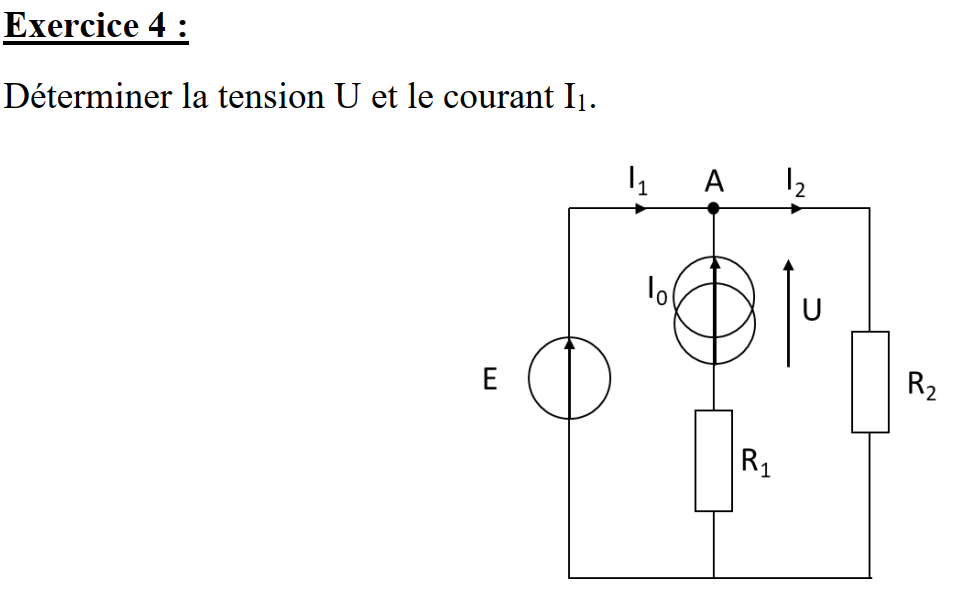

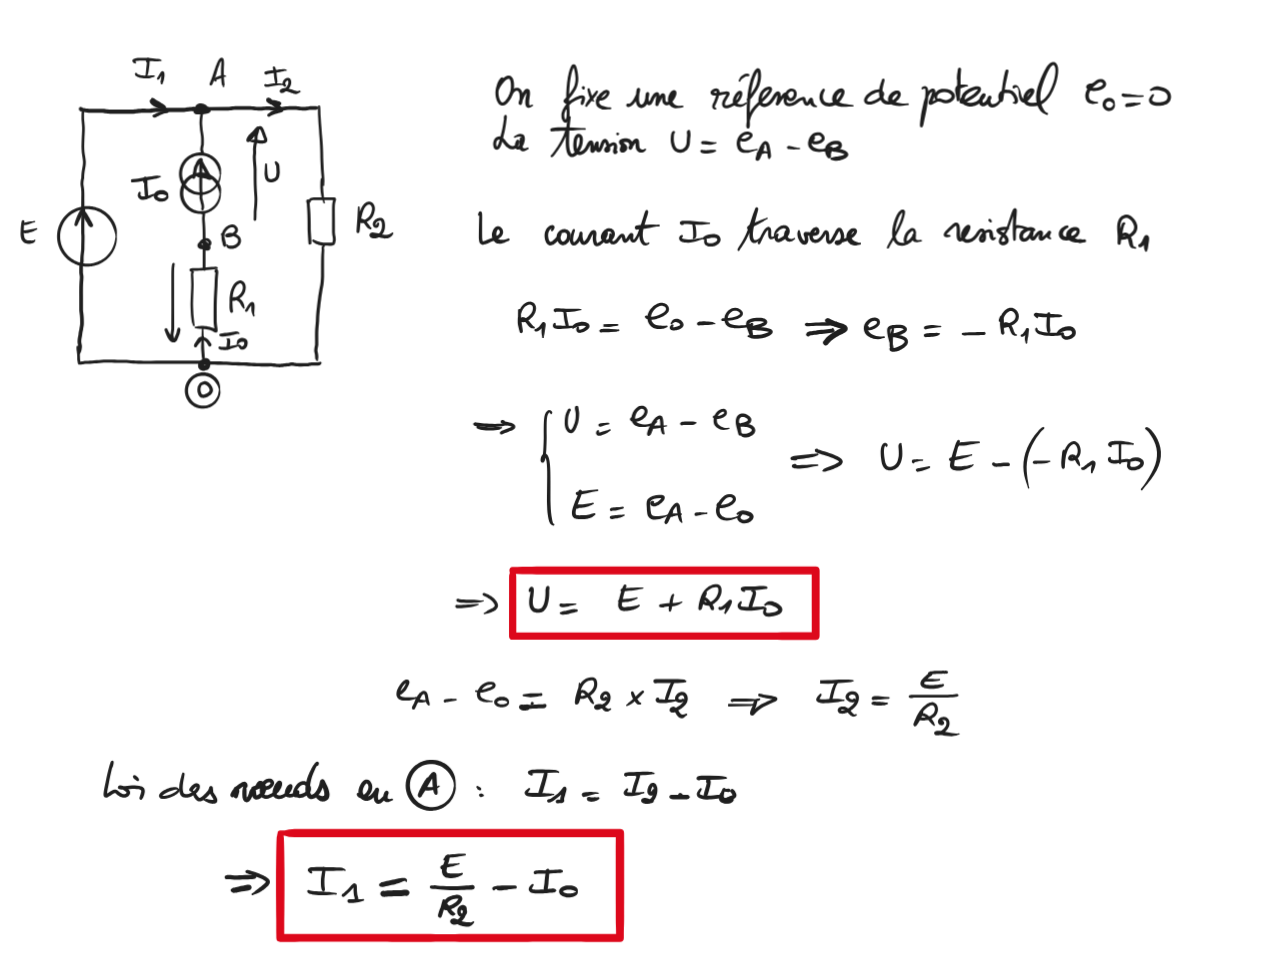

Utilisation de fspice :

netlist={
    'V1 A 0 E'
    'I1 B A I0'
    'R1 B 0 R1'
    'R2 A 0 R2'
    };
[X,name]=fspice(netlist)

** fspice 2.46  ** (c) Frederic Martinez


$$X = \left(\begin{array}{c} \text{E}\\ -I_{0}\,R_{1}\\ -\frac{\text{E}-I_{0}\,R_{2}}{R_{2}} \end{array}\right)$$

name = 1×3 cell array
    {'V(A)'}    {'V(B)'}    {'I(V1)'}


La tension U est $U=V(A)-V(B)$

U=X(1)-X(2)

$$U = \text{E}+I_{0}\,R_{1}$$

Par convention, le courant débité par la source de tension $I(V1)=-I_1$

I1=-X(3)

$$I1 = \frac{\text{E}-I_{0}\,R_{2}}{R_{2}}$$

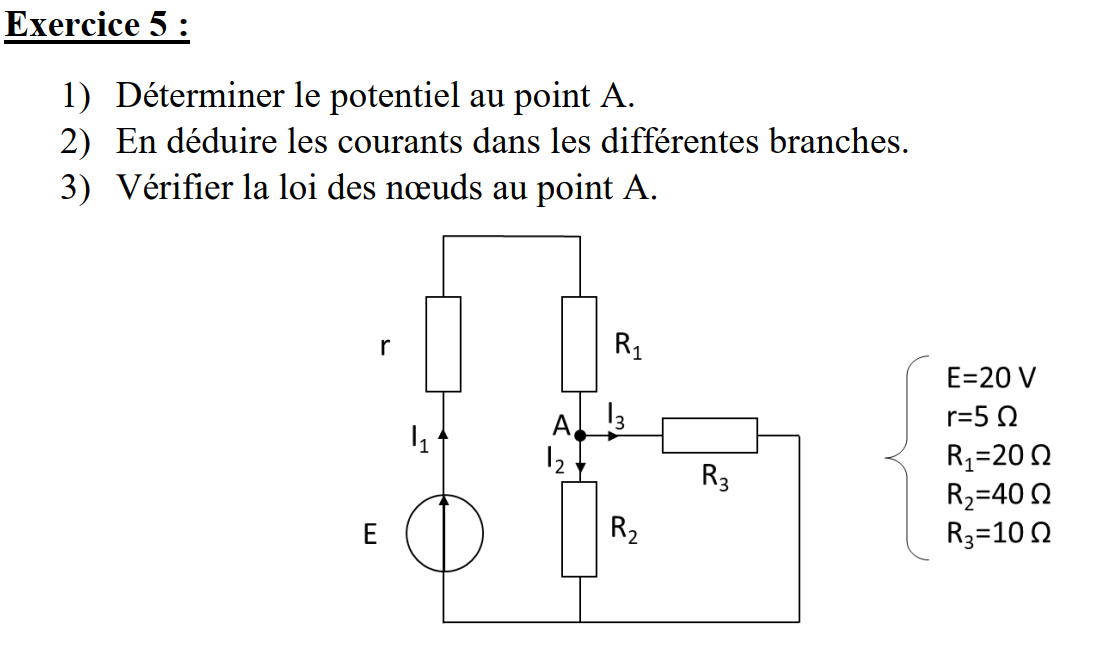

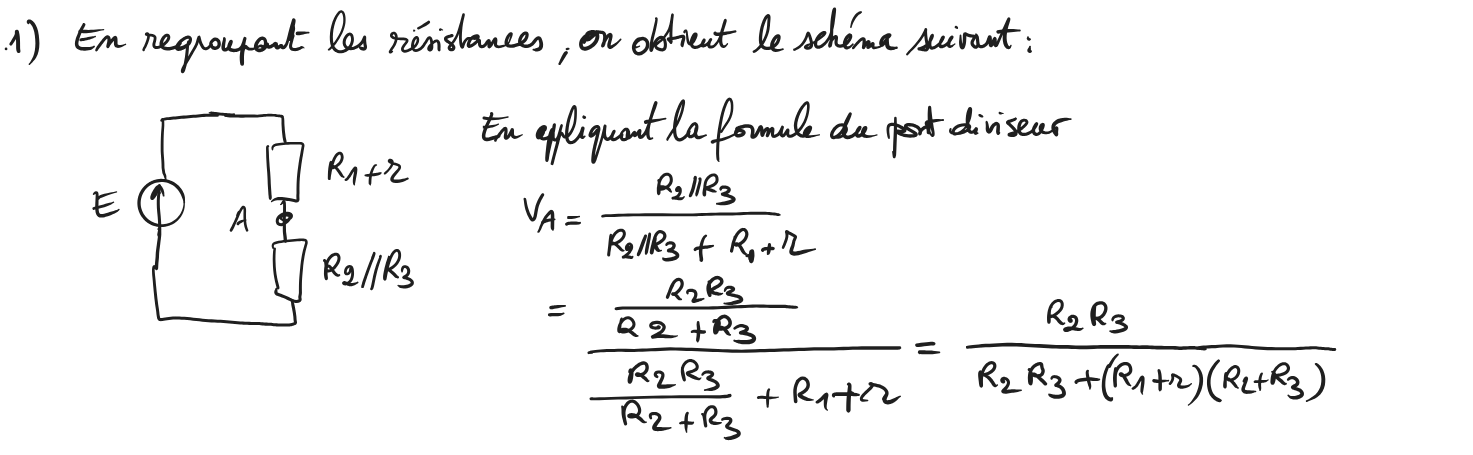

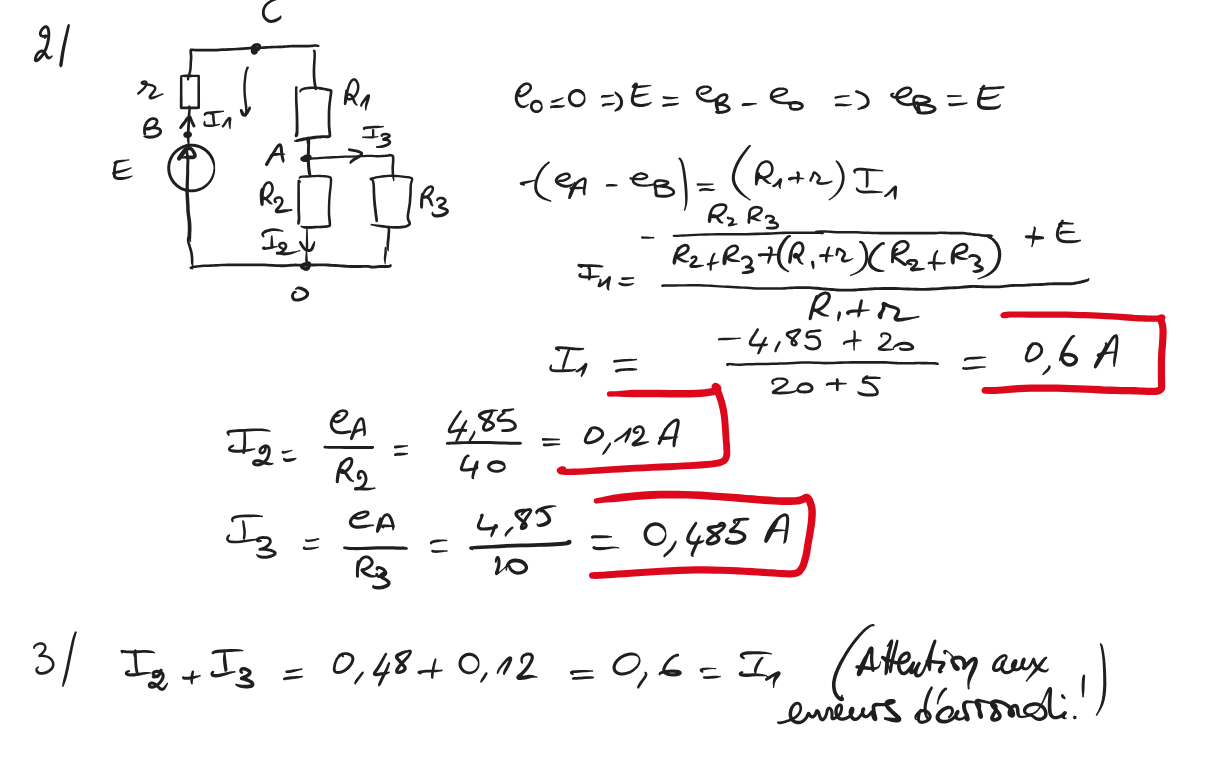

Utilisation de fspice :

netlist={
    'V1 B 0 E'
    'R1 B C r'
    'R2 C A R1'
    'R3 A 0 R2'
    'R4 A 0 R3'
    };
[X,name]=fspice(netlist)

** fspice 2.46  ** (c) Frederic Martinez


$$X = \begin{array}{l} \left(\begin{array}{c} \frac{\text{E}\,R_{2}\,R_{3}}{\sigma_{1}}\\ \text{E}\\ \frac{\text{E}\,\left(R_{1}\,R_{2}+R_{1}\,R_{3}+R_{2}\,R_{3}\right)}{\sigma_{1}}\\ -\frac{\text{E}\,\left(R_{2}+R_{3}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{1}\,R_{2}+R_{1}\,R_{3}+R_{2}\,R_{3}+R_{2}\,r+R_{3}\,r \end{array}$$

name = 1×4 cell array
    {'V(A)'}    {'V(B)'}    {'V(C)'}    {'I(V1)'}


Le courant $I_1$est, au signe près, le courant débité par la source de tension :

I1=-X(4)

$$I1 = \frac{\text{E}\,\left(R_{2}+R_{3}\right)}{R_{1}\,R_{2}+R_{1}\,R_{3}+R_{2}\,R_{3}+R_{2}\,r+R_{3}\,r}$$

Pour obtenir les courants $I_2$ et $I_3$, il faut utiliser les potentiels calculés au noeud A:

syms R2 R3
I2=X(1)/R2

$$I2 = \frac{\text{E}\,R_{3}}{R_{1}\,R_{2}+R_{1}\,R_{3}+R_{2}\,R_{3}+R_{2}\,r+R_{3}\,r}$$

I3=X(1)/R3

$$I3 = \frac{\text{E}\,R_{2}}{R_{1}\,R_{2}+R_{1}\,R_{3}+R_{2}\,R_{3}+R_{2}\,r+R_{3}\,r}$$

Application numérique :

R1=20;R2=40;R3=10;r=5;E=20;


$$V_A$$


double(subs(X(1)))

ans = 4.8485


$$I_1$$


double(subs(I1))

ans = 0.6061


$$I_2$$


double(subs(I2))

ans = 0.1212


$$I_3$$


double(subs(I3))

ans = 0.4848

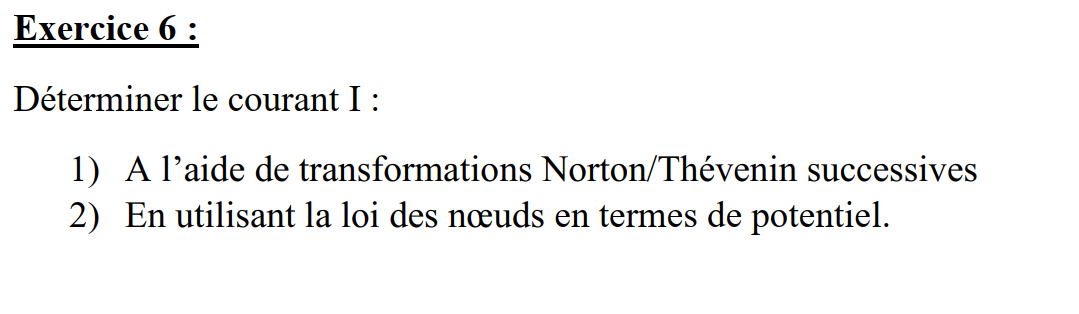

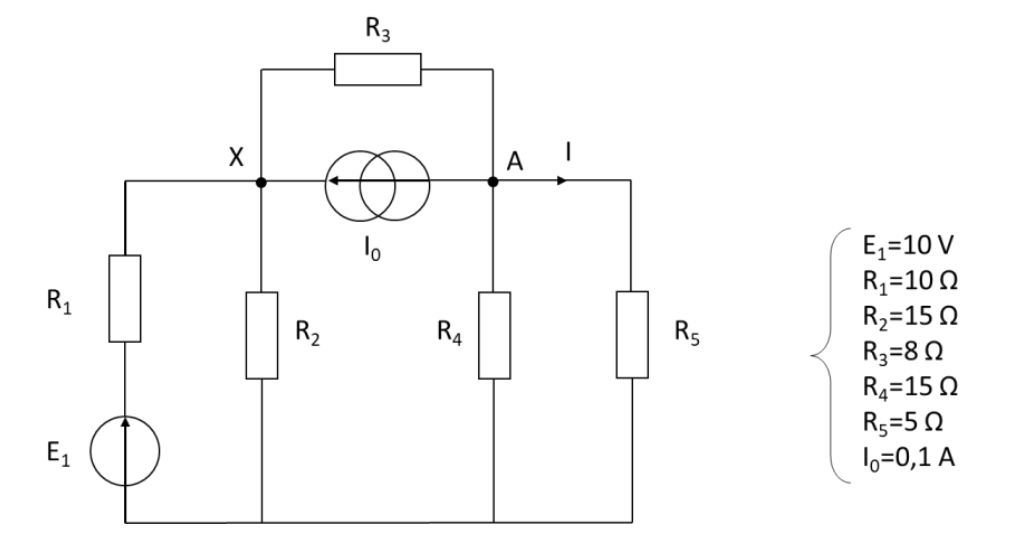

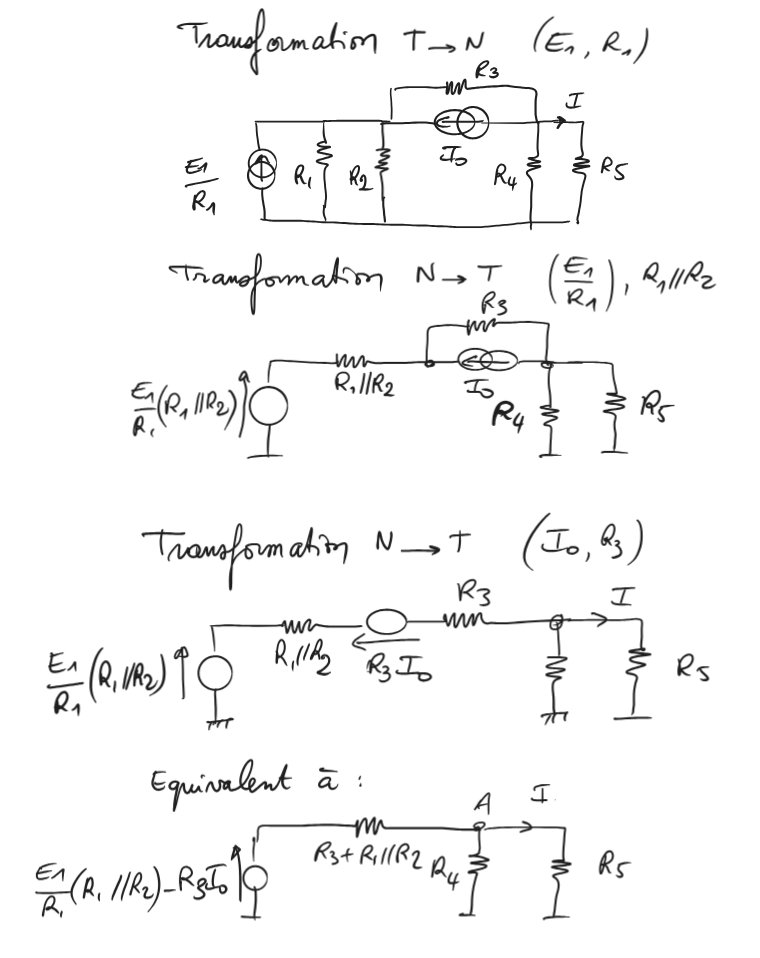

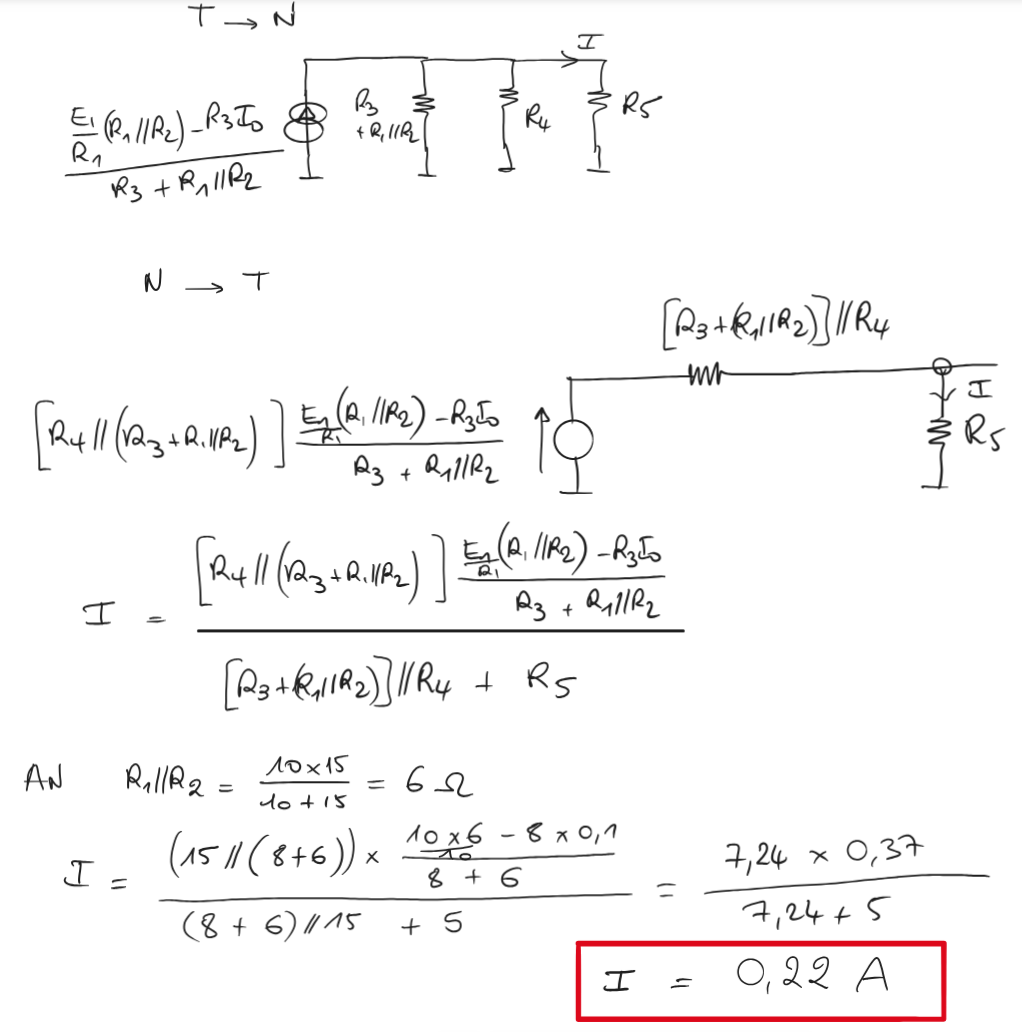

netlist={
    'V1 1 0 E1'
    'R1 1 XX R1'
    'R2 XX 0 R2'
    'R3 XX A R3'
    'R4 A 0 R4'
    'R5 A 0 R5'
    'I1 A XX I0'
    };
[X,name]=fspice(netlist)

** fspice 2.46  ** (c) Frederic Martinez


$$X = \begin{array}{l} \left(\begin{array}{c} E_{1}\\ -\frac{R_{4}\,R_{5}\,\left(I_{0}\,R_{1}\,R_{3}-E_{1}\,R_{2}+I_{0}\,R_{2}\,R_{3}\right)}{\sigma_{1}}\\ \frac{R_{2}\,\left(E_{1}\,R_{3}\,R_{4}+E_{1}\,R_{3}\,R_{5}+E_{1}\,R_{4}\,R_{5}+I_{0}\,R_{1}\,R_{3}\,R_{4}+I_{0}\,R_{1}\,R_{3}\,R_{5}\right)}{\sigma_{1}}\\ -\frac{E_{1}\,R_{2}\,R_{4}+E_{1}\,R_{2}\,R_{5}+E_{1}\,R_{3}\,R_{4}+E_{1}\,R_{3}\,R_{5}+E_{1}\,R_{4}\,R_{5}-I_{0}\,R_{2}\,R_{3}\,R_{4}-I_{0}\,R_{2}\,R_{3}\,R_{5}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{1}\,R_{2}\,R_{4}+R_{1}\,R_{2}\,R_{5}+R_{1}\,R_{3}\,R_{4}+R_{1}\,R_{3}\,R_{5}+R_{2}\,R_{3}\,R_{4}+R_{1}\,R_{4}\,R_{5}+R_{2}\,R_{3}\,R_{5}+R_{2}\,R_{4}\,R_{5} \end{array}$$

name = 1×4 cell array
    {'V(1)'}    {'V(A)'}    {'V(XX)'}    {'I(V1)'}


syms R5
I=X(2)/R5

$$I = -\frac{R_{4}\,\left(I_{0}\,R_{1}\,R_{3}-E_{1}\,R_{2}+I_{0}\,R_{2}\,R_{3}\right)}{R_{1}\,R_{2}\,R_{4}+R_{1}\,R_{2}\,R_{5}+R_{1}\,R_{3}\,R_{4}+R_{1}\,R_{3}\,R_{5}+R_{2}\,R_{3}\,R_{4}+R_{1}\,R_{4}\,R_{5}+R_{2}\,R_{3}\,R_{5}+R_{2}\,R_{4}\,R_{5}}$$

E1=10;R1=10;R2=15;R3=8;R4=15;R5=5;I0=0.1;
double(subs(I))

ans = 0.2197

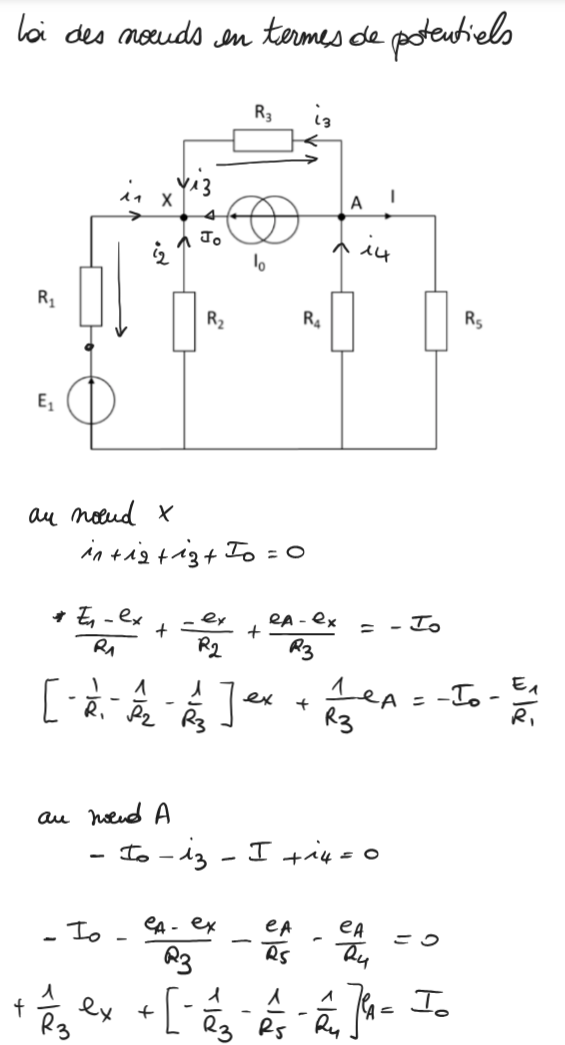

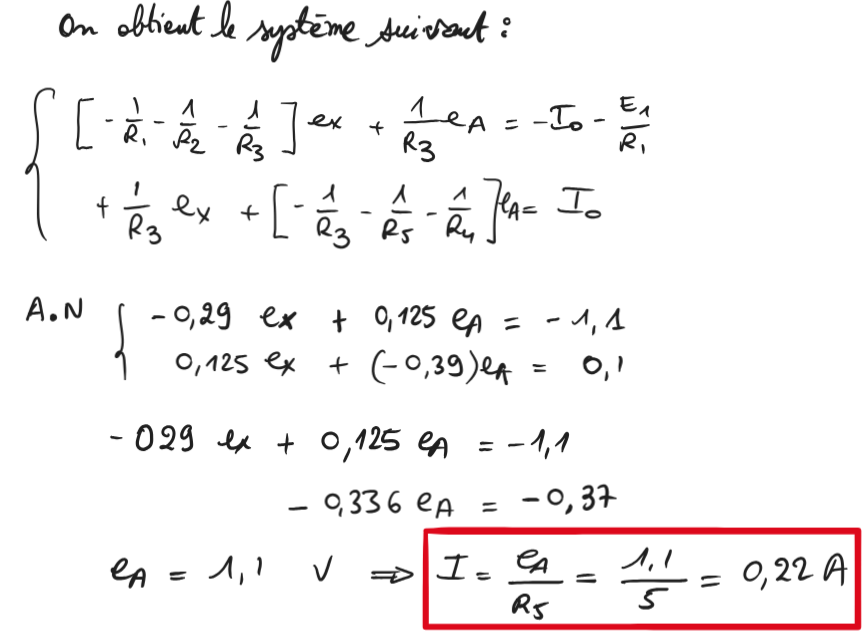

Résolution avec matlab du système d'équation  AX=B:

A=[-0.29 0.125;.125 -.39]

A =    -0.2900    0.1250
    0.1250   -0.3900


B=[-1.1;0.1]

B =    -1.1000
    0.1000


X=A^-1*B

X =     4.2729
    1.1131


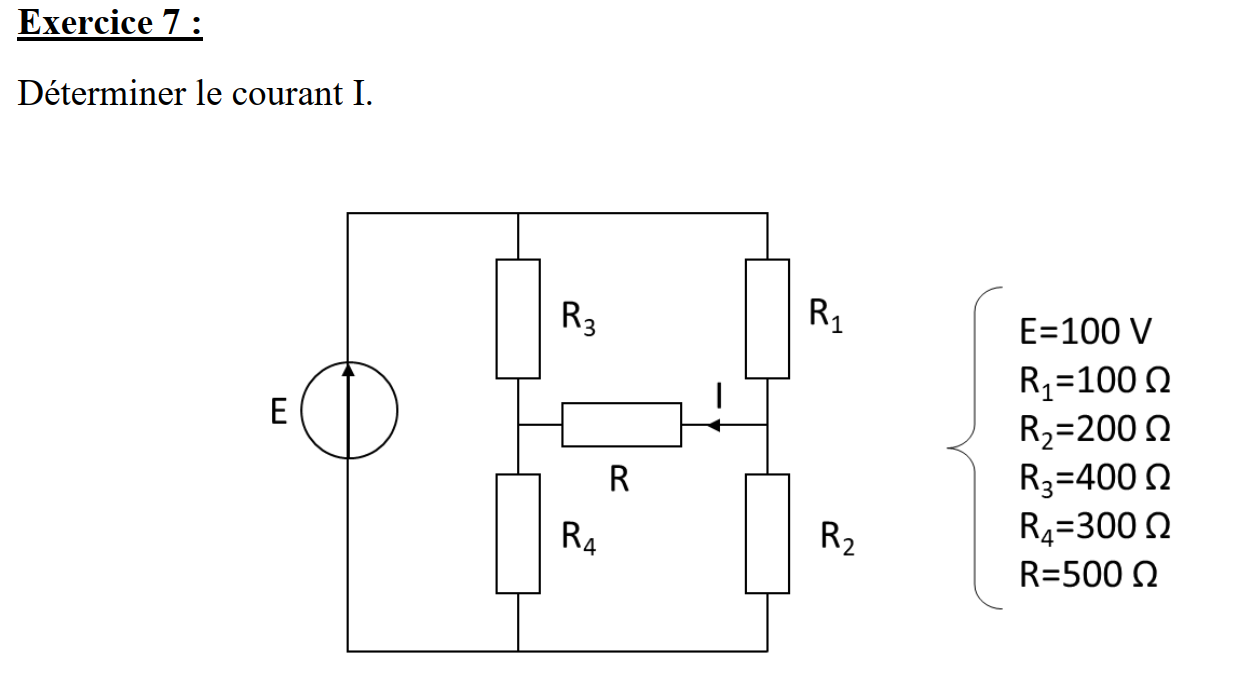.

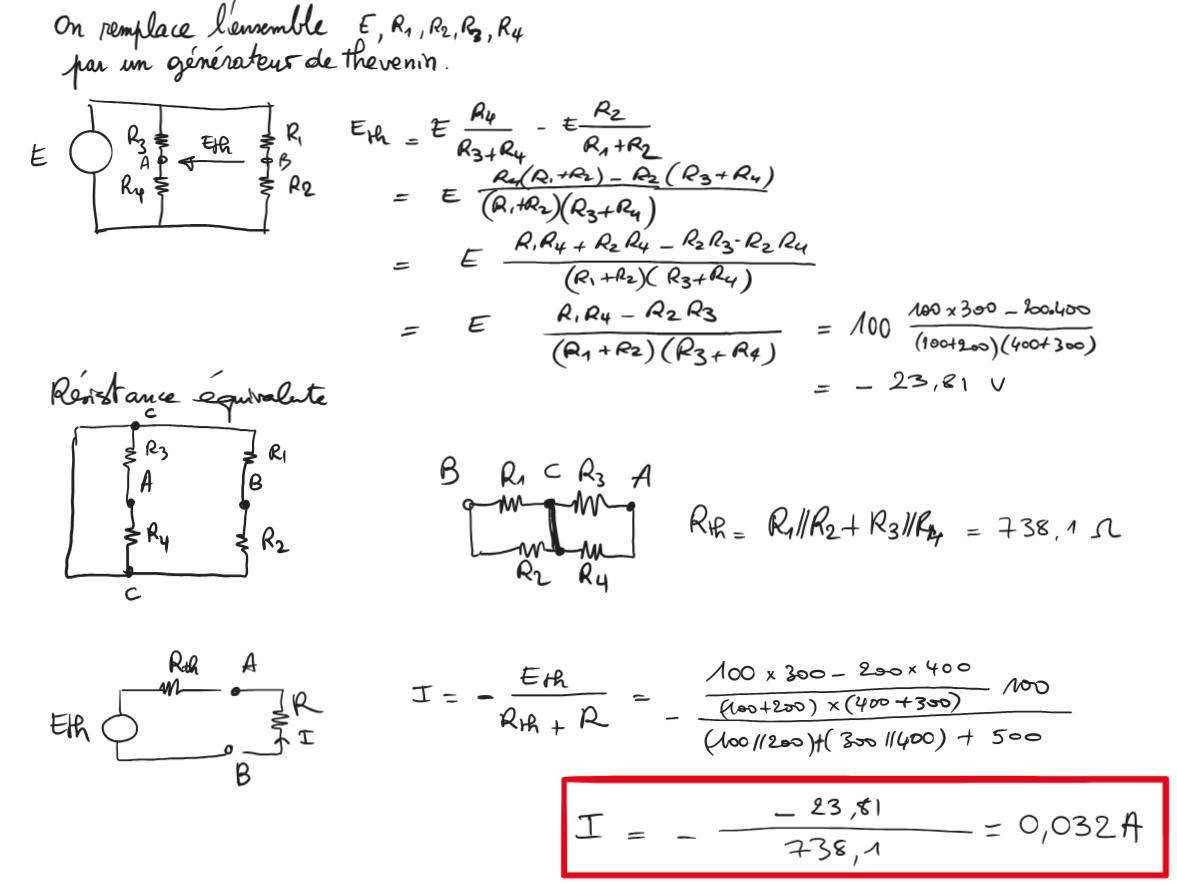

netlist={
    'V1 1 0 E'
    'R1 1 B R1'
    'R2 B 0 R2'
    'R3 1 A R3'
    'R4 A 0 R4'
    'R5 A B R'};
[X,name]=fspice(netlist)

** fspice 2.46  ** (c) Frederic Martinez


$$X = \begin{array}{l} \left(\begin{array}{c} \text{E}\\ \frac{\text{E}\,R_{4}\,\left(R\,R_{1}+R\,R_{2}+R_{1}\,R_{2}+R_{2}\,R_{3}\right)}{\sigma_{1}}\\ \frac{\text{E}\,R_{2}\,\left(R\,R_{3}+R\,R_{4}+R_{1}\,R_{4}+R_{3}\,R_{4}\right)}{\sigma_{1}}\\ -\frac{\text{E}\,\left(R\,R_{1}+R\,R_{2}+R\,R_{3}+R_{1}\,R_{2}+R\,R_{4}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{3}\,R_{4}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R\,R_{1}\,R_{3}+R\,R_{1}\,R_{4}+R\,R_{2}\,R_{3}+R\,R_{2}\,R_{4}+R_{1}\,R_{2}\,R_{3}+R_{1}\,R_{2}\,R_{4}+R_{1}\,R_{3}\,R_{4}+R_{2}\,R_{3}\,R_{4} \end{array}$$

name = 1×4 cell array
    {'V(1)'}    {'V(A)'}    {'V(B)'}    {'I(V1)'}


syms R
I=(X(3)-X(2))/R;
E=100;R1=100;R2=200;R3=400;R4=300;R=500;
double(subs(I))

ans = 0.0323